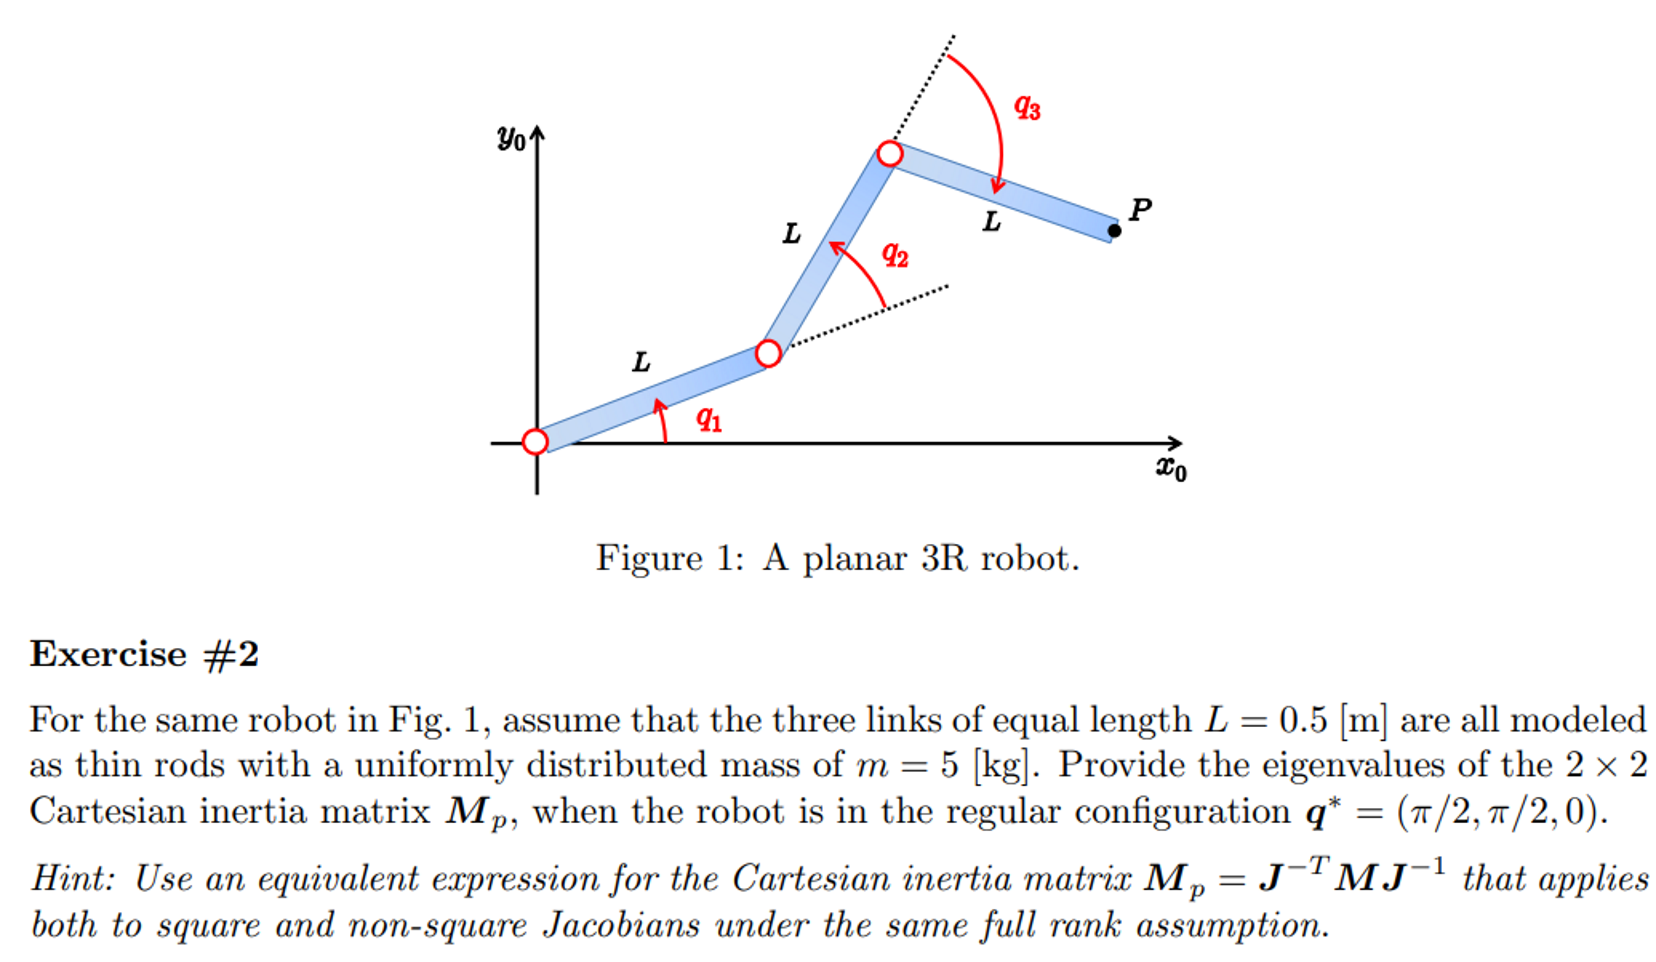

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 real
syms L m_1 m_2 m_3 I_1 I_2 I_3 g0 positive

% Dynamic model
% joint 1 
x1 = (L/2)*cos(q1);
y1 = (L/2)*sin(q1);

vx1 = diff(x1,q1)*q_dot_1 + diff(x1,q2)*q_dot_2 + diff(x1,q3)*q_dot_3;
vy1 = diff(y1,q1)*q_dot_1 + diff(y1,q2)*q_dot_2 + diff(y1,q3)*q_dot_3;

T1_tr = 0.5*m_1*[vx1 vy1]*[vx1; vy1;];
T1_rot = 0.5*((1/12)*m_1*(L^2))*[0 0 q_dot_1]*[0; 0; q_dot_1;];
T1 = simplify(T1_tr+T1_rot,steps=1000)

$$T1 = \frac{L^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{6}$$


% joint 2 
x2 = L*cos(q1)+(L/2)*cos(q1+q2);
y2 = L*sin(q1)+(L/2)*sin(q1+q2);

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2 + diff(x2,q3)*q_dot_3;
vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2 + diff(y2,q3)*q_dot_3;

T2_tr = 0.5*m_2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*((1/12)*m_2*(L^2))*[0 0 q_dot_1+q_dot_2]*[0; 0; q_dot_1+q_dot_2;];
T2 = T2_tr + T2_rot

$$T2 = \frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(\frac{L\,\cos\left(q_{1}+q_{2}\right)}{2}+L\,\cos\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(\frac{L\,\sin\left(q_{1}+q_{2}\right)}{2}+L\,\sin\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{L^{2}\,m_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{24}$$


% joint 3
x3 = L*cos(q1)+L*cos(q1+q2)+(L/2)*cos(q1+q2+q3);
y3 = L*sin(q1)+L*sin(q1+q2)+(L/2)*sin(q1+q2+q3);

vx3 = diff(x3,q1)*q_dot_1 + diff(x3,q2)*q_dot_2 + diff(x3,q3)*q_dot_3;
vy3 = diff(y3,q1)*q_dot_1 + diff(y3,q2)*q_dot_2 + diff(y3,q3)*q_dot_3;

T3_tr = 0.5*m_3*[vx3 vy3]*[vx3; vy3;];
T3_rot = 0.5*((1/12)*m_3*(L^2))*[0 0 q_dot_1+q_dot_2+q_dot_3]*[0; 0; q_dot_1+q_dot_2+q_dot_3;];
T3 = T3_tr + T3_rot

$$T3 = \begin{array}{l} \frac{m_{3}\,{\left({\dot{q}}_{2}\,\left(\sigma_{1}+\frac{L\,\sigma_{3}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{1}+L\,\sin\left(q_{1}\right)+\frac{L\,\sigma_{3}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{3}}{2}\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{2}\,\left(\sigma_{2}+\frac{L\,\sigma_{4}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{2}+L\,\cos\left(q_{1}\right)+\frac{L\,\sigma_{4}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{4}}{2}\right)}^{2}}{2}+\frac{L^{2}\,m_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{24}\\ \mathrm{where}\\ \sigma_{1}=L\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=L\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


% Total Energy
T = T1+T2+T3

$$T = \begin{array}{l} \frac{m_{3}\,{\left({\dot{q}}_{2}\,\left(\sigma_{1}+\frac{L\,\sigma_{3}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{1}+L\,\sin\left(q_{1}\right)+\frac{L\,\sigma_{3}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{3}}{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(\frac{\sigma_{2}}{2}+L\,\cos\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{m_{2}\,{\left({\dot{q}}_{1}\,\left(\frac{\sigma_{1}}{2}+L\,\sin\left(q_{1}\right)\right)+\frac{L\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\right)}^{2}}{2}+\frac{m_{3}\,{\left({\dot{q}}_{2}\,\left(\sigma_{2}+\frac{L\,\sigma_{4}}{2}\right)+{\dot{q}}_{1}\,\left(\sigma_{2}+L\,\cos\left(q_{1}\right)+\frac{L\,\sigma_{4}}{2}\right)+\frac{L\,{\dot{q}}_{3}\,\sigma_{4}}{2}\right)}^{2}}{2}+\frac{L^{2}\,m_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{24}+\frac{L^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{6}+\frac{L^{2}\,m_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{24}\\ \mathrm{where}\\ \sigma_{1}=L\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=L\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);
M13 = diff(diff(T, q_dot_1), q_dot_3);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);
M23 = diff(diff(T, q_dot_2), q_dot_3);

M31 = diff(diff(T, q_dot_3), q_dot_1);
M32 = diff(diff(T, q_dot_3), q_dot_2);
M33 = diff(diff(T, q_dot_3), q_dot_3);

M = [M11, M12, M13;
     M21, M22, M23;
     M31, M32, M33];
M = simplify(M);

M_subs2 = subs(M,[q1,q2,q3,L,m_1,m_2,m_3],[pi/2,pi/2,0,0.5,5,5,5])

$$M\_subs2 = \left(\begin{array}{ccc} \frac{25}{4} & \frac{10}{3} & \frac{25}{24}\\ \frac{10}{3} & \frac{10}{3} & \frac{25}{24}\\ \frac{25}{24} & \frac{25}{24} & \frac{5}{12} \end{array}\right)$$

M_subs = eval(subs(M,[q1,q2,q3,L,m_1,m_2,m_3],[pi/2,pi/2,0,0.5,5,5,5]))

M_subs =     6.2500    3.3333    1.0417
    3.3333    3.3333    1.0417
    1.0417    1.0417    0.4167



% Direct kinematics
r = [L*cos(q1)+L*cos(q1+q2)+L*cos(q1+q2+q3); L*sin(q1)+L*sin(q1+q2)+L*sin(q1+q2+q3);];

% Jacobian
J = jacobian(r,[q1,q2,q3]);
J_subs = subs(J,[q1,q2,q3,L],[pi/2,pi/2,0,0.5])

$$J\_subs = \left(\begin{array}{ccc} -\frac{1}{2} & 0 & 0\\ -1 & -1 & -\frac{1}{2} \end{array}\right)$$


% Natural Cartesian Inertia
M_p_inv = inv(M_subs);
M_p = eval(inv(J_subs*M_p_inv*(J_subs.')))

M_p =    11.6667    0.0000
    0.0000    1.4583



% Eigein Value of Natural Cartesian Inertia
eig_M_p = eig(M_p)

eig_M_p =     1.4583
   11.6667
